# **RT-QIBC analysis**

**FarRed2: EdU**

**YFP1: Chromatin-bound Cdc45**

**POI(:,2): APC/C inactivation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    'H2O/DMSO no dox',2:4,2,1:4,[0 0 0],'HU-','DMSO','Dox-'; %1
    'H2O/ATRi no dox',5:7,2,1:4,[0 0 0],'HU-','ATRi','Dox-'; %1
    
    'HU/DMSO no dox',2:4,3,1:4,[0 0 0],'HU+','DMSO','Dox-'; %1
    'HU/ATRi no dox',5:7,3,1:4,[0 0 0],'HU+','ATRi','Dox-'; %1
    
    'H2O/DMSO dox',2:4,4:6,1:4,[0 0 0],'HU-','DMSO','Dox+'; %1
    'H2O/ATRi dox',5:7,4:6,1:4,[0 0 0],'HU-','ATRi','Dox+'; %1
    
    'HU/DMSO dox',2:4,7:9,1:4,[0 0 0],'HU+','DMSO','Dox+'; %1
    'HU/ATRi dox',5:7,7:9,1:4,[0 0 0],'HU+','ATRi','Dox+'; %1
    };

load([dataDir filesep 'C156_data.mat'],'S');
%S = loadData_C154(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 65;
frameEdU = 0;
timeStart = 2.1;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

**Load data into table**

conds=1:8;
poiAligned=2;
offset=0;

dfTotal = table();

gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};

for i=1:length(conds)
    ind = true(size(S(conds(i)).sigNuc(:,1))) ;
    
    time=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    edu=(S(conds(i)).YFP2(ind));
    %cdc45=(S(conds(i)).YFP1(ind)-(S(conds(i)).YFP1cyt(ind)));
    cdc45=(S(conds(i)).YFP1(ind));
    
    
    gates = gateVals{i};
    for j=1:length(gates)
        %gateData = S(conds(i)).(gates{j})(ind);
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        time = time(inds);
        cdt1 = cdt1(inds);
        edu = edu(inds);
        cdc45 = cdc45(inds);
    end
    
    inds = time <= 3 & time >= 2;
    time = time(inds);
    cdt1 = cdt1(inds);
    edu = edu(inds);
    cdc45 = cdc45(inds);
   
    cdt1(cdt1<0.0001) = .0001;
%     edu(edu<0.0001) = .0001;
%     cdc45(cdc45<0.0001) = .0001;
    eduNorm = edu./cdc45;

    treatment = repmat(categorical(conditions(conds(i),1)),numel(time),1);
    HUtreatment = repmat(categorical(conditions(conds(i),6)),numel(time),1);
    ATRtreatment = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    doxTreatment = repmat(categorical(conditions(conds(i),8)),numel(time),1);
    
    dfTotal = [dfTotal;table(treatment, HUtreatment, ATRtreatment, doxTreatment,time,cdt1,edu,cdc45,eduNorm)];
end

dfTotal.drugTreatment = categorical(strcat(string(dfTotal.HUtreatment),{'\'},string(dfTotal.ATRtreatment)));
dfTotal = movevars(dfTotal,'drugTreatment','After','doxTreatment');

conds = [1];
for i=1:length(conds)
    
    ind = log2(S(conds(i)).dna) < 22 & S(conds(i)).apcNuc(:,end) < 20 & S(conds(i)).YFP2 < 300;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    edu=(S(conds(i)).YFP2(ind));
    %cdc45=(S(conds(i)).YFP1(ind)-(S(conds(i)).YFP1cyt(ind)));
    cdc45=(S(conds(i)).YFP1(ind));
    
    cdt1(cdt1<0.0001) = .0001;
%     edu(edu<0.0001) = .0001;
%     cdc45(cdc45<0.0001) = .0001;
    eduNorm = edu./cdc45;
    
    time = repmat(0,numel(cdt1),1);
    treatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    HUtreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    ATRtreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    doxTreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    drugTreatment = repmat(categorical(cellstr('G1')),numel(cdt1),1);
    dfTotal = [dfTotal; table(treatment, HUtreatment, ATRtreatment, doxTreatment,drugTreatment,time,cdt1,edu,cdc45,eduNorm)];
end


%dfTotal = dfTotal(dfTotal.eduNorm < 10,:);

Subset based on cdt1 expression

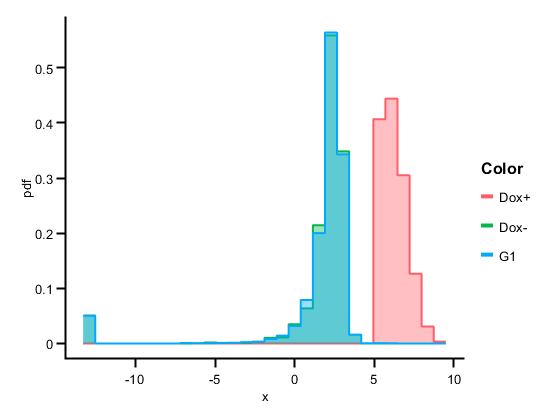

dfGated = dfTotal((log2(dfTotal.cdt1) > 5 & dfTotal.doxTreatment == 'Dox+') |...
    dfTotal.doxTreatment == 'Dox-' | dfTotal.treatment =='G1',:);

g= gramm('x',log2(dfGated.cdt1),'color',dfGated.doxTreatment);
g.stat_bin('geom','stairs','fill','transparent','normalization','pdf');
figure,
g.draw();

order = {'G1','H2O/DMSO no dox','H2O/DMSO dox','HU/DMSO no dox','HU/DMSO dox','HU/ATRi no dox','HU/ATRi dox',};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfGated.treatment == order{i} ;

    data = (dfGated.cdc45(inds));
    data(data > 600) = [];
    if length(data) > 1000
        data = randsample(data,1000,false);
    end
    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =         1000
         625
        1000
         729
         966
         503
         630


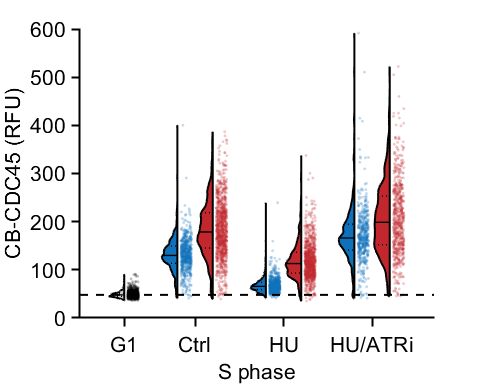

figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.7,'xValues',xkey,'widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 5,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel('CB-CDC45 (RFU)')
ylim([0 600])
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','Ctrl','HU','HU/ATRi'})
xlabel('S phase')
% xtickangle(45)
hline(median(dfGated.cdc45(dfGated.treatment == 'G1')),'k--')
% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\CDC45compare.pdf'])

order = {'G1','H2O/DMSO no dox','H2O/DMSO dox','HU/ATRi no dox','HU/ATRi dox',};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfGated.treatment == order{i} ;

    data = (dfGated.cdc45(inds));
    data(data > 600) = [];
    if length(data) > 1000
        data = randsample(data,1000,false);
    end
    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =         1000
         625
        1000
         503
         630
         503
         630


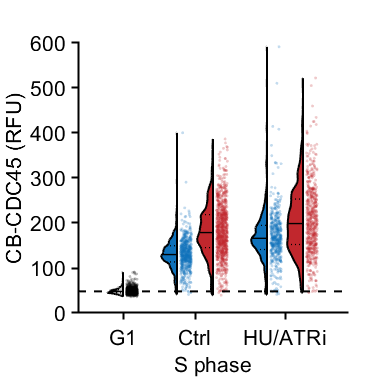

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.7,'xValues',xkey,'widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 5,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel('CB-CDC45 (RFU)')
ylim([0 600])
axis square 
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','Ctrl','HU/ATRi'})
xlabel('S phase')
% xtickangle(45)
hline(median(dfGated.cdc45(dfGated.treatment == 'G1')),'k--')
% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\CDC45compare_noHU.pdf'])

order = {'G1','H2O/DMSO no dox','H2O/DMSO dox','HU/DMSO no dox','HU/DMSO dox','HU/ATRi no dox','HU/ATRi dox',};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfGated.treatment == order{i};
    data = log2(dfGated.edu(inds));

    if length(data) > 1000
        data = randsample(data,1000,false);
    end
    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end

group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =         1000
         625
        1000
         729
         966
         504
         630


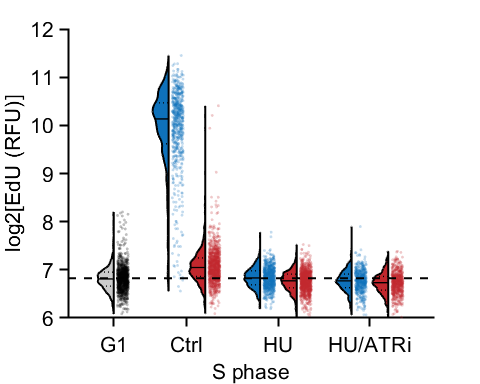

figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.7,'xValues',xkey,'widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 5,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel('log2[EdU (RFU)]')
ylim([6 12])
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','Ctrl','HU','HU/ATRi'})
xlabel('S phase')
% xtickangle(45)
hline(median(log2(dfGated.edu(dfGated.treatment == 'G1'))),'k--')
% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\educompare.pdf'])

order = {'G1','H2O/DMSO no dox','H2O/DMSO dox','HU/ATRi no dox','HU/ATRi dox',};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfGated.treatment == order{i};

    data = log2(dfGated.edu(inds));

    if length(data) > 1000
        data = randsample(data,1000,false);
    end
    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end

group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =         1000
         625
        1000
         504
         630
         503
         630


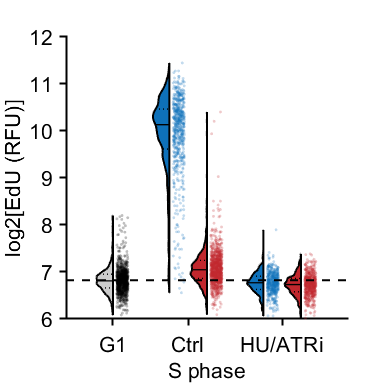

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.7,'xValues',xkey,'widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 5,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel('log2[EdU (RFU)]')
axis square
ylim([6 12])
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G1','Ctrl','HU/ATRi'})
xlabel('S phase')
% xtickangle(45)
hline(median(log2(dfGated.edu(dfGated.treatment == 'G1'))),'k--')
% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\educompare_noHU.pdf'])